%% ==============================================================
%  The sparse and low-rank interpretation of SVD-based denoising
%  ==============================================================
%  Methods implemented:
%  1. TSVD  - Truncated SVD (Hard Thresholding)
%  2. RSVD  - Reweighted SVD (Heuristic)
%  3. WSSVD - Weighted Soft SVD (Proposed)
%  4. WNNM  - weighted nuclear norm minimization 
%  ============================================================

clc;
clear;
close all;

%% ============================================================
%  BLOCK 1: LOAD RAW IMS DATA (1D TIME SIGNAL)
%  ============================================================
%  The dataset consists of raw vibration signals
%  sampled at 20 kHz.
%  ============================================================

Fs = 1000;                      % Sampling frequency (Hz)
filePath = "..\data\2004.02.19.04.02.39";   % CHANGE IF NEEDED

y = load(filePath);              % Load raw vibration signal
y = y(:);                        % Ensures column vector

fprintf('Loaded signal length: %d samples\n', length(y));

Loaded signal length: 81920 samples


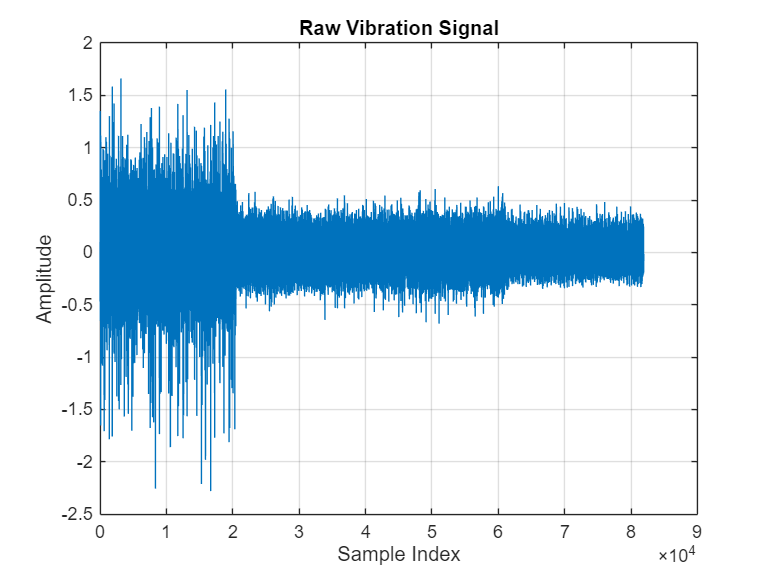


% Plot raw signal
figure;
plot(y);
title('Raw Vibration Signal');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

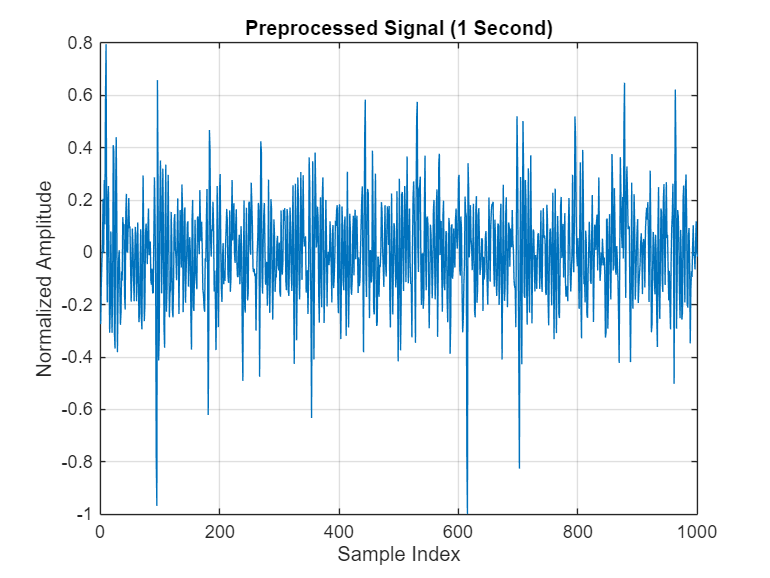


%% ============================================================
%  BLOCK 2: SIGNAL PREPROCESSING (1D)
%  ============================================================
%  Purpose:
%  - Remove DC offset
%  - Normalize amplitude
%  - Select manageable segment
%  ============================================================

T = 1;                           % 1 second segment
N = Fs * T;

y_seg = y(1:N);                  % Segment selection
y_seg = y_seg - mean(y_seg);     % Mean removal
y_seg = y_seg / max(abs(y_seg)); % Normalization

figure;
plot(y_seg);
title('Preprocessed Signal (1 Second)');
xlabel('Sample Index');
ylabel('Normalized Amplitude');
grid on;


%% ============================================================
%  BLOCK 3: MATRIX CONSTRUCTION
%  ============================================================
%  Overlap = l - 1 gives Hankel structure
%  ============================================================

l = 40;                  % Patch length
overlap = l - 1;         % Maximum overlap

Y = buffer(y_seg, l, overlap, 'nodelay');

fprintf('Constructed matrix size: %d x %d\n', size(Y,1), size(Y,2));

Constructed matrix size: 40 x 961


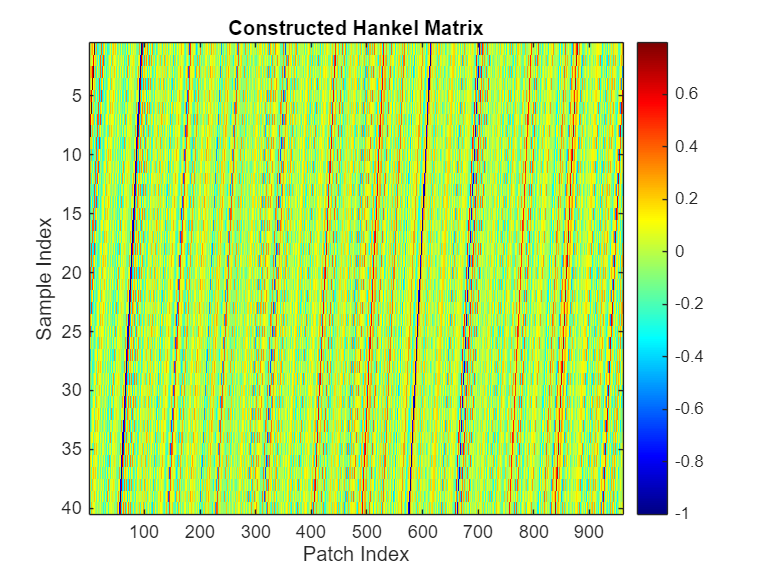


figure;
imagesc(Y);
colormap jet;
colorbar;
title('Constructed Hankel Matrix');
xlabel('Patch Index');
ylabel('Sample Index');


fprintf('\n--- Hankel Matrix Verification ---\n');


--- Hankel Matrix Verification ---


fprintf('First 5 elements of first column:\n');

First 5 elements of first column:


disp(Y(1:5,1));

   -0.2740
   -0.1237
   -0.0362
    0.0455
    0.2046




fprintf('First 5 elements of last column:\n');

First 5 elements of last column:


disp(Y(1:5,end));

   -0.5019
    0.1318
    0.6222
    0.3914
   -0.2911




fprintf('Frobenius norm of Y: %.6f\n', norm(Y,'fro'));

Frobenius norm of Y: 37.858977



%% ============================================================
%  BLOCK 4: SVD DECOMPOSITION
%  ============================================================
%  Y = U * Sigma * V^T
%  ============================================================

[U, S, V] = svd(Y, 'econ');
sigma = diag(S);

fprintf('\n--- SVD Verification ---\n');


--- SVD Verification ---


fprintf('Top 10 singular values:\n');

Top 10 singular values:


disp(sigma(1:10));

   12.6960
   12.6738
   12.1057
   11.9715
    8.8361
    8.7587
    7.2761
    7.0351
    6.4830
    6.4245




energy_total = sum(sigma.^2);
energy_top10 = sum(sigma(1:10).^2);

fprintf('Energy retained by top 10 SVs: %.2f %%\n', ...
        100 * energy_top10 / energy_total);

Energy retained by top 10 SVs: 66.43 %


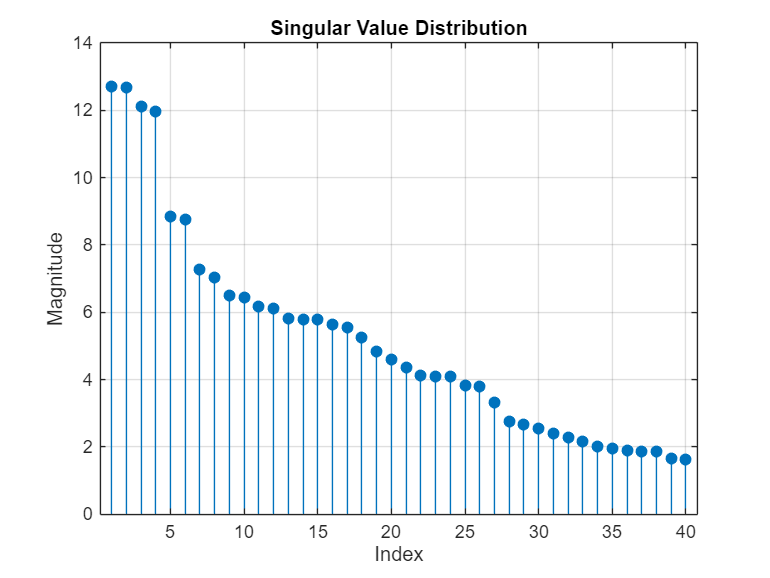


figure;
stem(sigma, 'filled');
title('Singular Value Distribution');
xlabel('Index');
ylabel('Magnitude');
grid on;


%% ============================================================
%  BLOCK 5: TSVD (TRUNCATED SVD)
%  ============================================================
%  TSVD = Hard thresholding of singular values
%  ============================================================
lambda = 0.05; 

sigma_t = sign(sigma) .* max(abs(sigma), sqrt(2*lambda));

S_tsvd = diag(sigma_t);

X_tsvd = U * S_tsvd * V';

%% ============================================================
%  BLOCK 6: RSVD
%  ============================================================
%  RSVD uses Periodic Modulation Intensity (PMI)
%  to identify fault-related components.
%  ============================================================

numSV = length(sigma);
PMI = zeros(numSV,1);

for i = 1:numSV
    
    % i-th right singular vector
    vi = V(:,i);
    
    % Envelope of vi
    env_vi = abs(hilbert(vi));
    env_vi = env_vi - mean(env_vi); %DC removal
    
    % FFT of envelope
    L = length(env_vi);
    NFFT = 2^nextpow2(L);
    ENV_FFT = fft(env_vi, NFFT);
    
    mag = abs(ENV_FFT(1:NFFT/2+1));
    
    % PMI = Ratio of maximum spectral peak to average spectral energy
    PMI(i) = max(mag) / (mean(mag) + eps);
end

% Normalize PMI to [0,1]
PMI = PMI / max(PMI);

% RSVD singular value reweighting
sigma_rsvd = PMI .* sigma;

S_rsvd = diag(sigma_rsvd);

X_rsvd = U * S_rsvd * V';

%% ============================================================
%  BLOCK 7: WSSVD (WEIGHTED SOFT SVD) - PROPOSED METHOD
%  ============================================================
%  Uses weighted soft thresholding
%  ============================================================

lambda = 0.05;                     % Regularization parameter

w = 1 ./ (sigma / max(sigma) + eps);   % Weights

sigma_w = sign(sigma) .* max(abs(sigma) - lambda * w, 0);

S_wssvd = diag(sigma_w);

X_wssvd = U * S_wssvd * V';

%% ============================================================
% BLOCK 7: WNNM (WEIGHTED NUCLEAR NORM MINIMIZATION)
% -------------------------------------------------------------
% Closed-form solution via weighted singular value shrinkage
% ============================================================

lambda=0.05;   % data fidelity parameter

% Weight design
w_wnnm = 1 ./ (sigma + eps);   

% Weighted soft-thresholding
sigma_wnnm = max(sigma - (w_wnnm*lambda), 0);

% Reconstruct diagonal matrix
S_wnnm = diag(sigma_wnnm);

% WNNM denoised matrix
X_wnnm = U * S_wnnm * V';

%---------------------------------------------------------------
fprintf('\n--- Singular Value Modification ---\n');


--- Singular Value Modification ---



fprintf('Original sigma (first 10):\n');

Original sigma (first 10):


disp(sigma(1:10));

   12.6960
   12.6738
   12.1057
   11.9715
    8.8361
    8.7587
    7.2761
    7.0351
    6.4830
    6.4245




fprintf('TSVD sigma (first 10):\n');

TSVD sigma (first 10):


disp(diag(S_tsvd(1:10,1:10)));

   12.6960
   12.6738
   12.1057
   11.9715
    8.8361
    8.7587
    7.2761
    7.0351
    6.4830
    6.4245




fprintf('RSVD sigma (first 10):\n');

RSVD sigma (first 10):


disp(diag(S_rsvd(1:10,1:10)));

    9.1951
    8.5189
    5.9450
    5.6126
    8.8361
    8.5491
    2.7944
    2.3911
    5.1397
    3.2991




fprintf('WSSVD sigma (first 10):\n');

WSSVD sigma (first 10):


disp(diag(S_wssvd(1:10,1:10)));

   12.6460
   12.6237
   12.0533
   11.9185
    8.7642
    8.6862
    7.1889
    6.9449
    6.3851
    6.3257




fprintf('WNNM sigma (first 10):\n');

WNNM sigma (first 10):


disp(diag(S_wnnm(1:10,1:10)));

   12.6921
   12.6698
   12.1016
   11.9673
    8.8304
    8.7530
    7.2693
    7.0280
    6.4753
    6.4167




%% ============================================================
%  BLOCK 8: SIGNAL RECONSTRUCTION
%  ============================================================

x_tsvd  = reconstruct_signal(X_tsvd,  l, overlap);
x_rsvd  = reconstruct_signal(X_rsvd,  l, overlap);
x_wssvd = reconstruct_signal(X_wssvd, l, overlap);
x_wnnm  = reconstruct_signal(X_wnnm,  l, overlap);

%% ============================================================
% QUANTITATIVE AMPLITUDE FIDELITY METRICS
% =============================================================
% To quantitatively evaluate the amplitude fidelity of SVD-based denoising 
% methods by measuring how well signal amplitude, energy, and impulsive 
% characteristics are preserved after denoising.
% ============================================================

% Ensure equal length
x0 = y_seg(:);
xT = x_tsvd(1:N); % Truncated SVD
xR = x_rsvd(1:N); % Reweighted SVD
xW = x_wssvd(1:N); % Weighted soft SVD
xw = x_wnnm(1:N); % Weighted Nuclear Norm Minimization

%% ---------------- RMS Preservation ----------------
RMS_orig = rms(x0);
RMS_tsvd = rms(xT);
RMS_rsvd = rms(xR);
RMS_wssvd = rms(xW);
RMS_wnnm = rms(xw);

RMS_ratio_tsvd = RMS_tsvd / RMS_orig;
RMS_ratio_rsvd = RMS_rsvd / RMS_orig;
RMS_ratio_wssvd = RMS_wssvd / RMS_orig;
RMS_ratio_wnnm = RMS_wnnm / RMS_orig;

%% ---------------- Peak-to-Peak Preservation ----------------
PP_orig = peak2peak(x0);
PP_tsvd = peak2peak(xT);
PP_rsvd = peak2peak(xR);
PP_wssvd = peak2peak(xW);
PP_wnnm = peak2peak(xw);

PP_ratio_tsvd = PP_tsvd / PP_orig;
PP_ratio_rsvd = PP_rsvd / PP_orig;
PP_ratio_wssvd = PP_wssvd / PP_orig;
PP_ratio_wnnm = PP_wnnm / PP_orig;

%% ---------------- Energy Retention ----------------
E_orig = sum(x0.^2);
E_tsvd = sum(xT.^2);
E_rsvd = sum(xR.^2);
E_wssvd = sum(xW.^2);
E_wnnm = sum(xw.^2);

E_ratio_tsvd = E_tsvd / E_orig;
E_ratio_rsvd = E_rsvd / E_orig;
E_ratio_wssvd = E_wssvd / E_orig;
E_ratio_wnnm = E_wnnm/ E_orig;

%% ---------------- Kurtosis (Impulsiveness) ----------------
K_orig = kurtosis(x0);
K_tsvd = kurtosis(xT);
K_rsvd = kurtosis(xR);
K_wssvd = kurtosis(xW);
K_wnnm = kurtosis(xw);

%% ---------------- Display Results ----------------
fprintf('\n========== AMPLITUDE FIDELITY METRICS ==========\n');


========== AMPLITUDE FIDELITY METRICS ==========



fprintf('RMS Preservation Ratio:\n');

RMS Preservation Ratio:


fprintf(' TSVD  : %.4f\n', RMS_ratio_tsvd);

 TSVD  : 1.0000


fprintf(' RSVD  : %.4f\n', RMS_ratio_rsvd);

 RSVD  : 0.5579


fprintf(' WSSVD : %.4f\n', RMS_ratio_wssvd);

 WSSVD : 0.9827


fprintf(' WNNM  : %.4f\n', RMS_ratio_wnnm);

 WNNM  : 0.9986



fprintf('\nPeak-to-Peak Preservation Ratio:\n');


Peak-to-Peak Preservation Ratio:


fprintf(' TSVD  : %.4f\n', PP_ratio_tsvd);

 TSVD  : 1.0000


fprintf(' RSVD  : %.4f\n', PP_ratio_rsvd);

 RSVD  : 0.4588


fprintf(' WSSVD : %.4f\n', PP_ratio_wssvd);

 WSSVD : 0.9704


fprintf(' WNNM  : %.4f\n', PP_ratio_wnnm);

 WNNM  : 0.9977



fprintf('\nEnergy Retention Ratio:\n');


Energy Retention Ratio:


fprintf(' TSVD  : %.4f\n', E_ratio_tsvd);

 TSVD  : 1.0000


fprintf(' RSVD  : %.4f\n', E_ratio_rsvd);

 RSVD  : 0.3112


fprintf(' WSSVD : %.4f\n', E_ratio_wssvd);

 WSSVD : 0.9656


fprintf(' WNNM  : %.4f\n', E_ratio_wnnm);

 WNNM  : 0.9972



fprintf('\nKurtosis (Impulsiveness):\n');


Kurtosis (Impulsiveness):


fprintf(' Original : %.4f\n', K_orig);

 Original : 5.1116


fprintf(' TSVD     : %.4f\n', K_tsvd);

 TSVD     : 5.1116


fprintf(' RSVD     : %.4f\n', K_rsvd);

 RSVD     : 3.7839


fprintf(' WSSVD    : %.4f\n', K_wssvd);

 WSSVD    : 4.9769


fprintf(' WNNM     : %.4f\n', K_wnnm);

 WNNM     : 5.1007



%% QUANTITATIVE METRICS TO CALCULATE RECONSTRUCTION ERROR

err_tsvd  = norm(y_seg - x_tsvd(1:N)) / norm(y_seg);
err_rsvd  = norm(y_seg - x_rsvd(1:N)) / norm(y_seg);
err_wssvd = norm(y_seg - x_wssvd(1:N)) / norm(y_seg);
err_wnnm = norm(y_seg - x_wnnm(1:N)) / norm(y_seg);

fprintf('\n--- Reconstruction Error (Relative) ---\n');


--- Reconstruction Error (Relative) ---


fprintf('TSVD  Error: %.4f\n', err_tsvd);

TSVD  Error: 0.0000


fprintf('RSVD  Error: %.4f\n', err_rsvd);

RSVD  Error: 0.4978


fprintf('WSSVD Error: %.4f\n', err_wssvd);

WSSVD Error: 0.0328


fprintf('WNNM Error : %.4f\n', err_wnnm);

WNNM Error : 0.0026


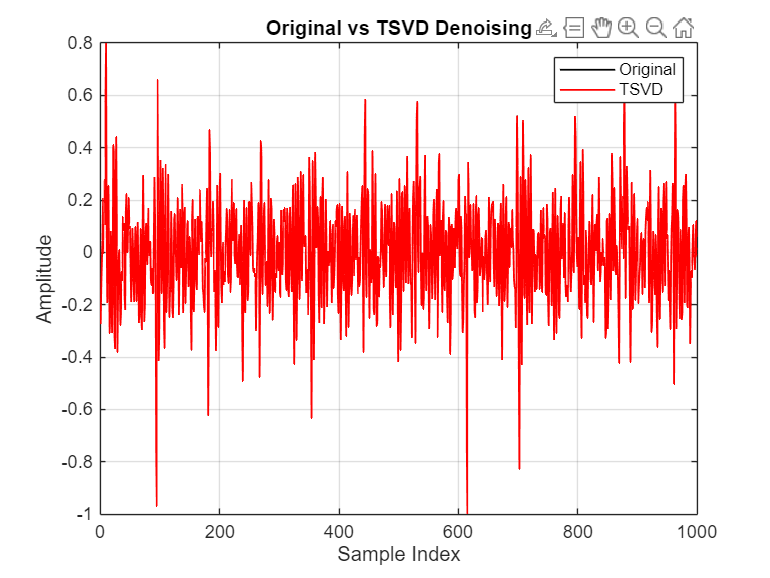


%% ============================================================
%  BLOCK 9: TIME-DOMAIN COMPARISON (INDIVIDUAL FIGURES)
%  ============================================================

%% ---------- Original vs TSVD ----------
figure;
plot(y_seg, 'k','LineWidth',1); hold on;
plot(x_tsvd, 'r','LineWidth',1);
legend('Original','TSVD');
title('Original vs TSVD Denoising');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

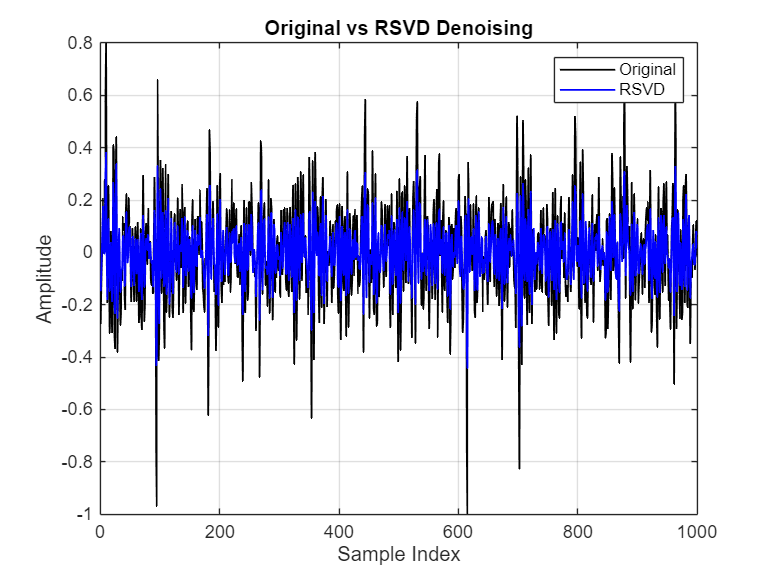



%% ---------- Original vs RSVD ----------
figure;
plot(y_seg, 'k','LineWidth',1); hold on;
plot(x_rsvd, 'b','LineWidth',1);
legend('Original','RSVD');
title('Original vs RSVD Denoising');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

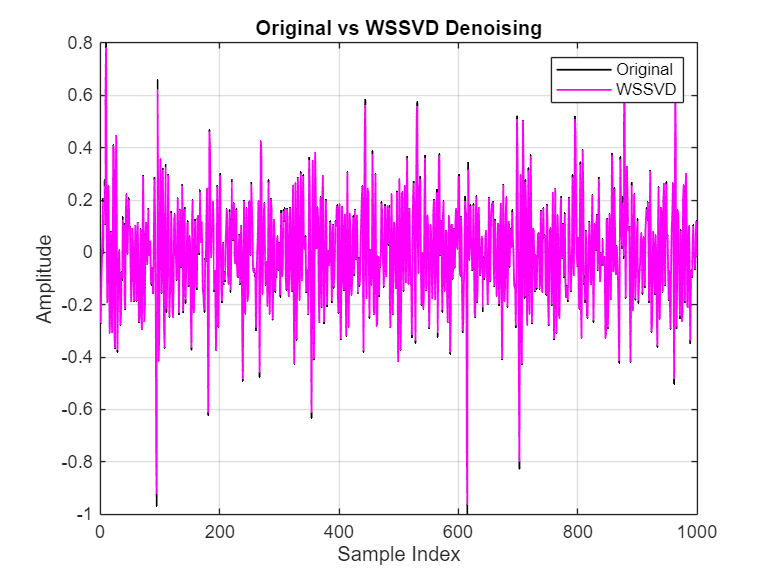



%% ---------- Original vs WSSVD ----------
figure;
plot(y_seg, 'k','LineWidth',1); hold on;
plot(x_wssvd, 'm','LineWidth',1);
legend('Original','WSSVD');
title('Original vs WSSVD Denoising');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

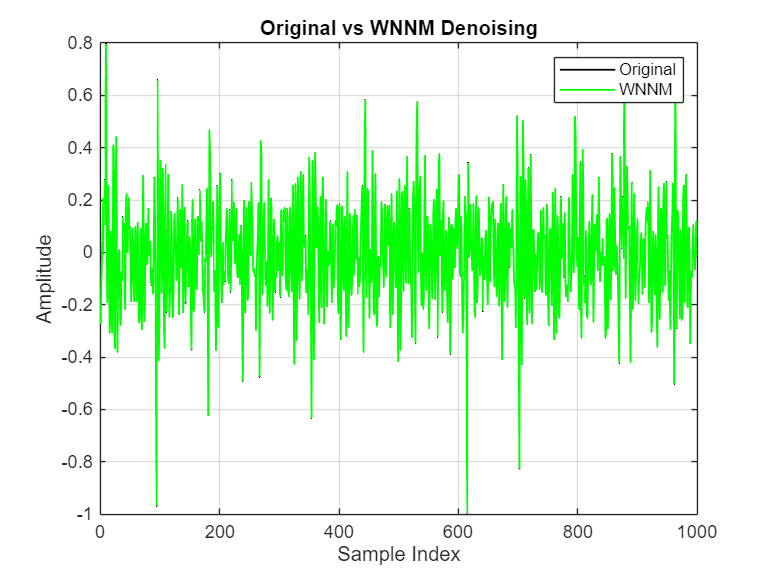



%% ---------- Original vs WNNM ----------
figure;
plot(y_seg, 'k','LineWidth',1); hold on;
plot(x_wnnm, 'g','LineWidth',1);
legend('Original','WNNM');
title('Original vs WNNM Denoising');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;



%% ============================================================
%  FUNCTION: SIGNAL RECONSTRUCTION
%  ============================================================
function x_rec = reconstruct_signal(X, l, overlap)

    [~, n] = size(X);
    step = l - overlap;
    x_len = l + (n-1)*step;

    x_rec = zeros(x_len,1);
    weight = zeros(x_len,1);

    for k = 1:n
        idx = (k-1)*step + (1:l);
        x_rec(idx) = x_rec(idx) + X(:,k);
        weight(idx) = weight(idx) + 1;
    end

    x_rec = x_rec ./ weight;
end

%% ============================================================
%  MATRIX-LEVEL COMPARISON (BEFORE vs AFTER DENOISING)
%  ============================================================

fprintf('\n========== MATRIX COMPARISON ==========\n');


========== MATRIX COMPARISON ==========



% Dimensions
fprintf('Original Matrix Y size      : %d x %d\n', size(Y,1), size(Y,2));

Original Matrix Y size      : 40 x 961


fprintf('WSSVD Matrix size           : %d x %d\n', size(X_wssvd,1), size(X_wssvd,2));

WSSVD Matrix size           : 40 x 961



% Frobenius norms
norm_Y  = norm(Y, 'fro');
norm_Xw = norm(X_wssvd, 'fro');

fprintf('Frobenius norm of Y         : %.4f\n', norm_Y);

Frobenius norm of Y         : 37.8590


fprintf('Frobenius norm of WSSVD(Y)  : %.4f\n', norm_Xw);

Frobenius norm of WSSVD(Y)  : 37.2042



% Relative change
fprintf('Relative norm reduction    : %.2f %%\n', ...
        100*(norm_Y - norm_Xw)/norm_Y);

Relative norm reduction    : 1.73 %


%% ============================================================
%  FAULT FREQUENCY CALCULATION (IMS BEARING)
%  ============================================================

% Bearing parameters (IMS dataset - standard)
fr = 2000/60;      % Shaft speed in Hz
n  = 8;            % Number of rolling elements
d  = 7.92e-3;      % Ball diameter (m)
D  = 34.55e-3;     % Pitch diameter (m)
theta = 0;         % Contact angle (rad)

% Fault frequencies
BPFO = (n/2)*fr*(1 - (d/D)*cos(theta));
BPFI = (n/2)*fr*(1 + (d/D)*cos(theta));

fprintf('\n--- Fault Frequencies ---\n');


--- Fault Frequencies ---


fprintf('Shaft frequency (fr): %.2f Hz\n', fr);

Shaft frequency (fr): 33.33 Hz


fprintf('BPFO: %.2f Hz\n', BPFO);

BPFO: 102.77 Hz


fprintf('BPFI: %.2f Hz\n', BPFI);

BPFI: 163.90 Hz


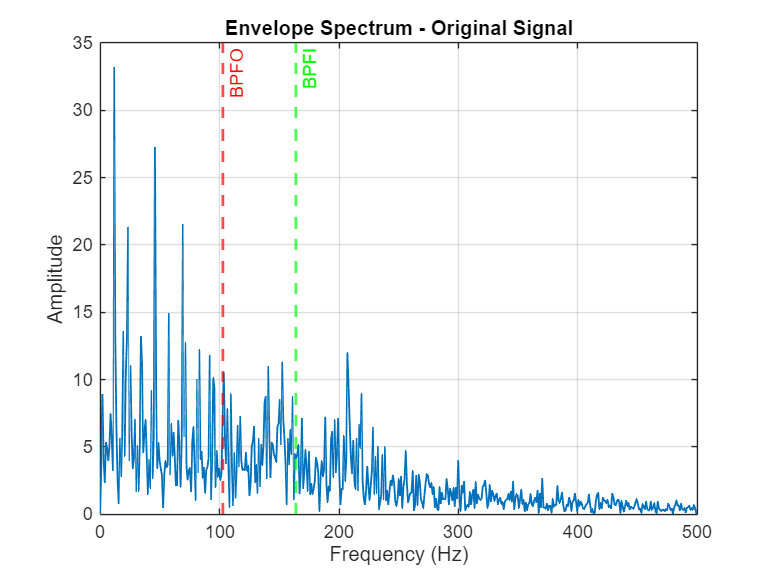

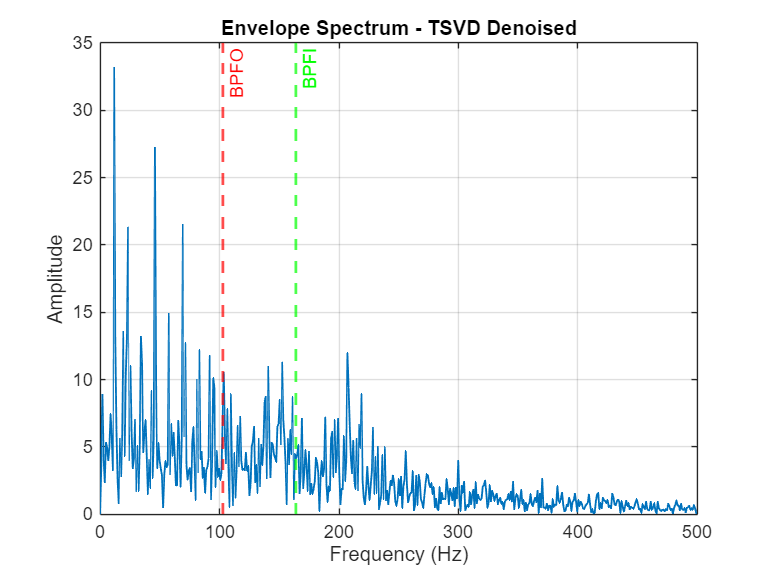

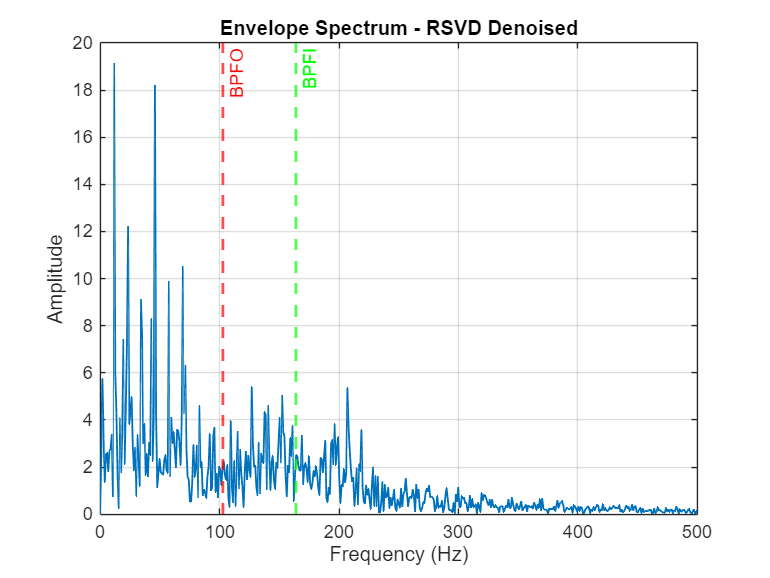

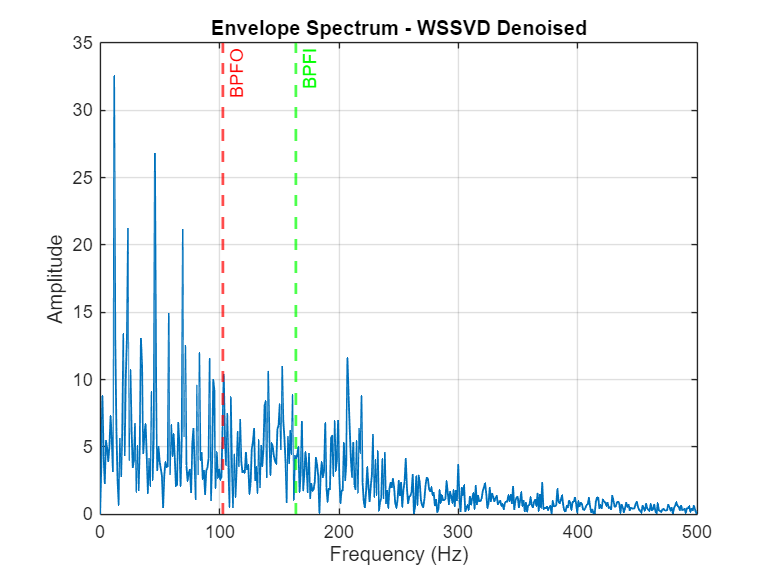

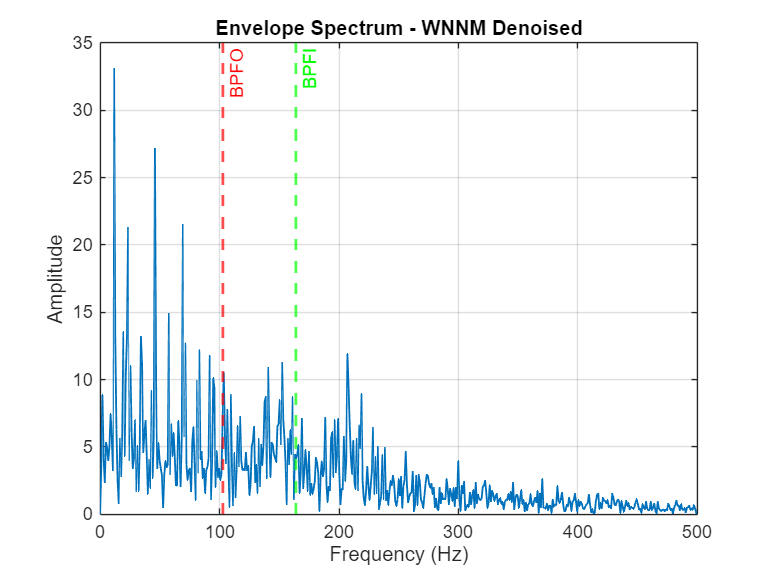

%% ============================================================
%  ENVELOPE SPECTRUM ANALYSIS
%  -> Envelope spectrum is used to reveal fault frequencies
%  Each signal will produce an individual figure
%  ============================================================

signals = { ...
    y_seg, ...
    x_tsvd(1:N), ...
    x_rsvd(1:N), ...
    x_wssvd(1:N), ...
    x_wnnm(1:N) ...
};

signal_names = { ...
    'Original Signal', ...
    'TSVD Denoised', ...
    'RSVD Denoised', ...
    'WSSVD Denoised', ...
    'WNNM Denoised' ...
};

for k = 1:length(signals)

    x = signals{k};

    %% Step 1: Hilbert transform
    x_hilbert = hilbert(x);

    %% Step 2: Envelope extraction
    envelope = abs(x_hilbert);

    %% Step 3: Remove DC component
    envelope = envelope - mean(envelope);

    %% Step 4: FFT of envelope
    L = length(envelope);
    NFFT = 2^nextpow2(L);

    ENV_FFT = fft(envelope, NFFT);

    f = Fs*(0:(NFFT/2))/NFFT;
    mag = abs(ENV_FFT(1:NFFT/2+1));

    %% Step 5: Plot envelope spectrum (INDIVIDUAL FIGURE)

    figure;  % Creates a new figure for every signal

    plot(f, mag, 'LineWidth', 1);

    xlim([0 500]);  % Fault frequencies are usually low

    xlabel('Frequency (Hz)');
    ylabel('Amplitude');

    title(['Envelope Spectrum - ', signal_names{k}]);

    grid on;

    hold on;

    xline(BPFO, '--r', 'BPFO', 'LineWidth', 1.5);
    xline(BPFI, '--g', 'BPFI', 'LineWidth', 1.5);

    hold off;

end

%% ============================================================
%  RESONANCE BAND EXTRACTION
%  ============================================================

% Typical resonance band for IMS bearings
f_low  = 50;   % Hz
f_high = min(300, Fs/2 - 10); % Hz

[b, a] = butter(4, [f_low f_high]/(Fs/2), 'bandpass');

% Apply to TSVD signal
x_tsvd_bp = filtfilt(b, a, x_tsvd(1:N));

% Apply to RSVD signal
x_rsvd_bp = filtfilt(b, a, x_rsvd(1:N));

% Apply to WSSVD signal
x_wssvd_bp = filtfilt(b, a, x_wssvd(1:N));

% Apply to WNNM signal
x_wnnm_bp = filtfilt(b, a, x_wnnm(1:N));

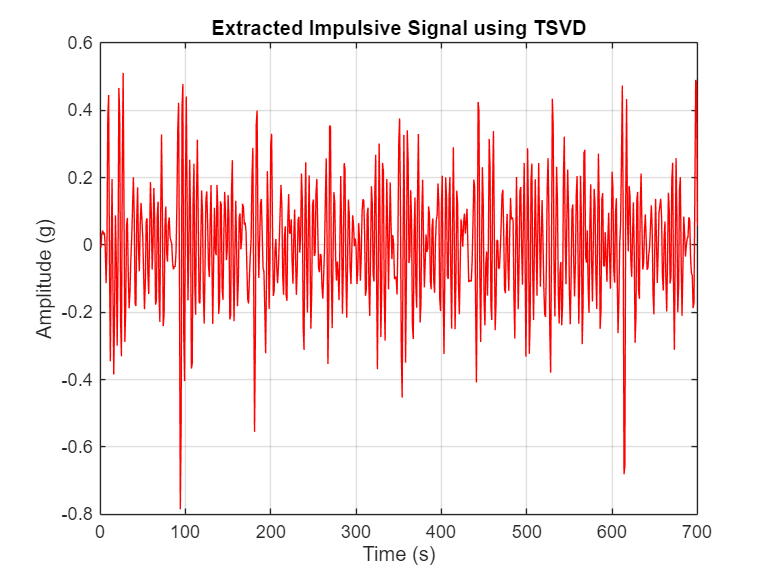

%% ============================================================
%  IMPULSIVE TIME SIGNAL 
%  ============================================================

T_plot = 0.7;                    % seconds
Ns = round(T_plot * Fs);

figure;
plot(x_tsvd_bp(1:Ns), 'r');
xlabel('Time (s)');
ylabel('Amplitude (g)');
title('Extracted Impulsive Signal using TSVD');
grid on;

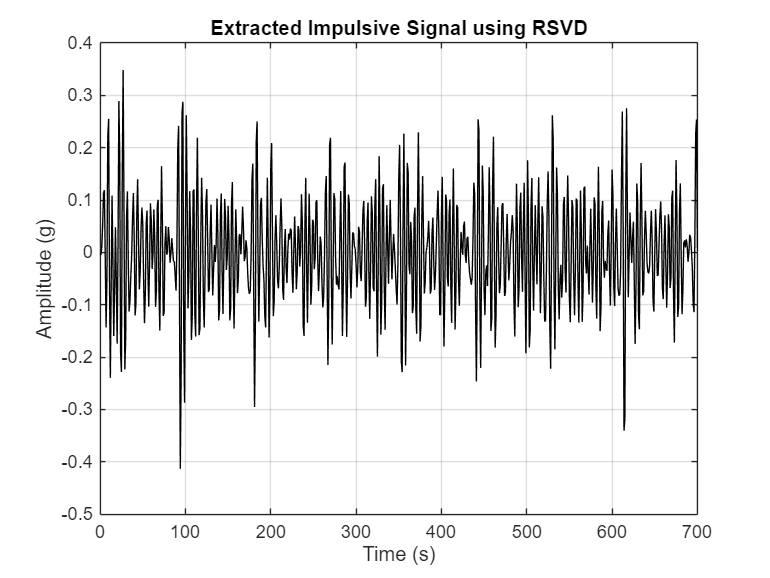


figure;
plot(x_rsvd_bp(1:Ns), 'k');
xlabel('Time (s)');
ylabel('Amplitude (g)');
title('Extracted Impulsive Signal using RSVD');
grid on;

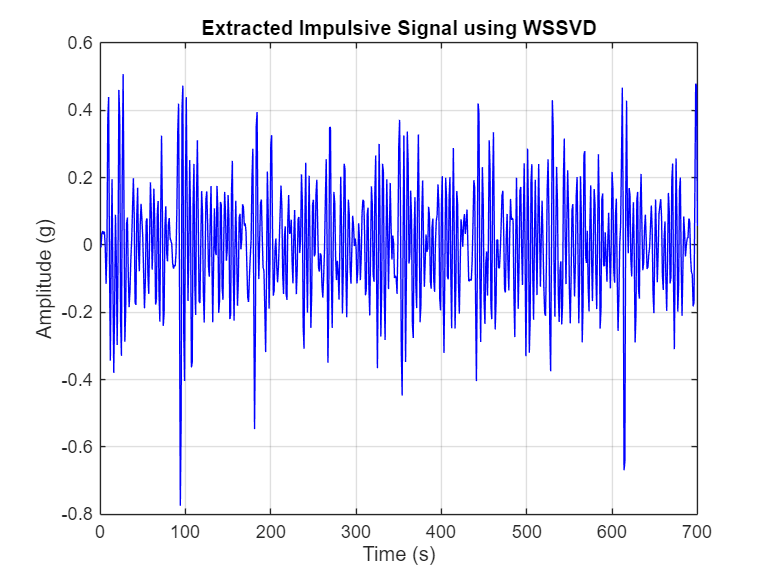


figure;
plot(x_wssvd_bp(1:Ns), 'b');
xlabel('Time (s)');
ylabel('Amplitude (g)');
title('Extracted Impulsive Signal using WSSVD');
grid on;

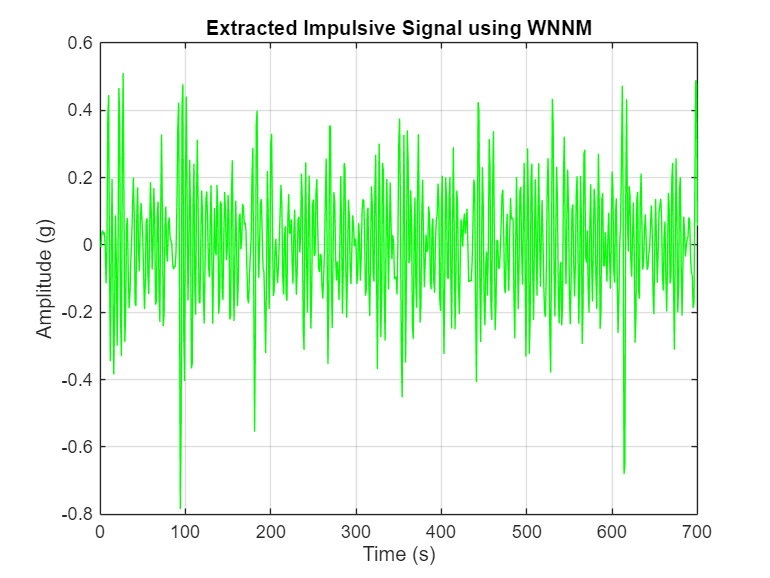


figure;
plot(x_wnnm_bp(1:Ns), 'g');
xlabel('Time (s)');
ylabel('Amplitude (g)');
title('Extracted Impulsive Signal using WNNM');
grid on;

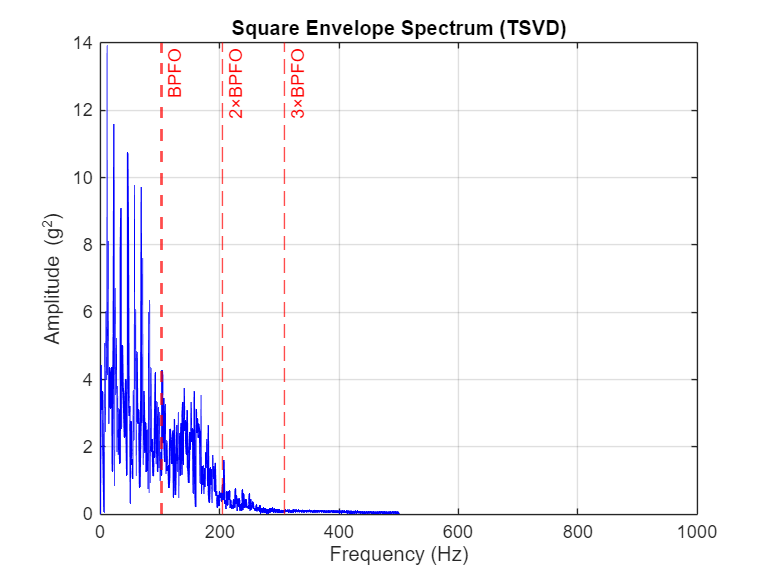

%% ============================================================
%  SQUARE ENVELOPE SPECTRUM for TSVD
%  ============================================================

x = x_tsvd_bp(1:Ns);

env = abs(hilbert(x));
env_sq = env.^2;
env_sq = env_sq - mean(env_sq);

L = length(env_sq);
NFFT = 2^nextpow2(L);
ENV_FFT = fft(env_sq, NFFT);

f = Fs*(0:(NFFT/2))/NFFT;
mag = abs(ENV_FFT(1:NFFT/2+1));

figure;
plot(f, mag, 'b', 'LineWidth', 1);
xlim([0 1000]);
xlabel('Frequency (Hz)');
ylabel('Amplitude (g^2)');
title('Square Envelope Spectrum (TSVD)');
grid on;

hold on;
xline(BPFO, '--r', 'BPFO', 'LineWidth', 1.5);
xline(2*BPFO, '--r', '2×BPFO');
xline(3*BPFO, '--r', '3×BPFO');
hold off;

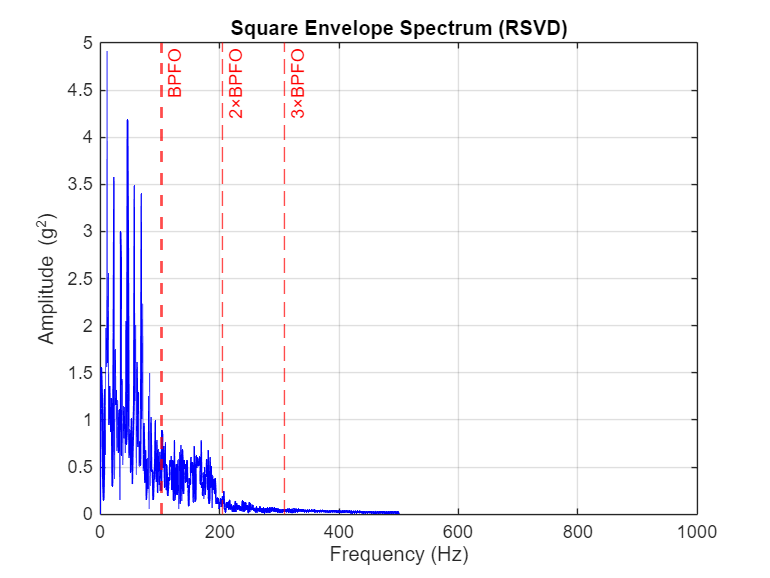

%% ============================================================
%  SQUARE ENVELOPE SPECTRUM for RSVD
%  ============================================================

x = x_rsvd_bp(1:Ns);

env = abs(hilbert(x));
env_sq = env.^2;
env_sq = env_sq - mean(env_sq);

L = length(env_sq);
NFFT = 2^nextpow2(L);
ENV_FFT = fft(env_sq, NFFT);

f = Fs*(0:(NFFT/2))/NFFT;
mag = abs(ENV_FFT(1:NFFT/2+1));

figure;
plot(f, mag, 'b', 'LineWidth', 1);
xlim([0 1000]);
xlabel('Frequency (Hz)');
ylabel('Amplitude (g^2)');
title('Square Envelope Spectrum (RSVD)');
grid on;

hold on;
xline(BPFO, '--r', 'BPFO', 'LineWidth', 1.5);
xline(2*BPFO, '--r', '2×BPFO');
xline(3*BPFO, '--r', '3×BPFO');
hold off;

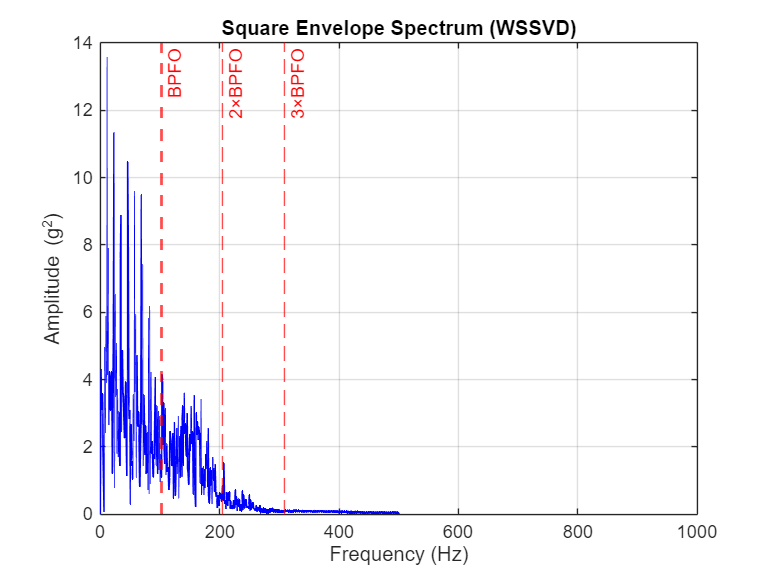

%% ============================================================
%  SQUARE ENVELOPE SPECTRUM 
%  ============================================================

x = x_wssvd_bp(1:Ns);

env = abs(hilbert(x));
env_sq = env.^2;
env_sq = env_sq - mean(env_sq);

L = length(env_sq);
NFFT = 2^nextpow2(L);
ENV_FFT = fft(env_sq, NFFT);

f = Fs*(0:(NFFT/2))/NFFT;
mag = abs(ENV_FFT(1:NFFT/2+1));

figure;
plot(f, mag, 'b', 'LineWidth', 1);
xlim([0 1000]);
xlabel('Frequency (Hz)');
ylabel('Amplitude (g^2)');
title('Square Envelope Spectrum (WSSVD)');
grid on;

hold on;
xline(BPFO, '--r', 'BPFO', 'LineWidth', 1.5);
xline(2*BPFO, '--r', '2×BPFO');
xline(3*BPFO, '--r', '3×BPFO');
hold off;

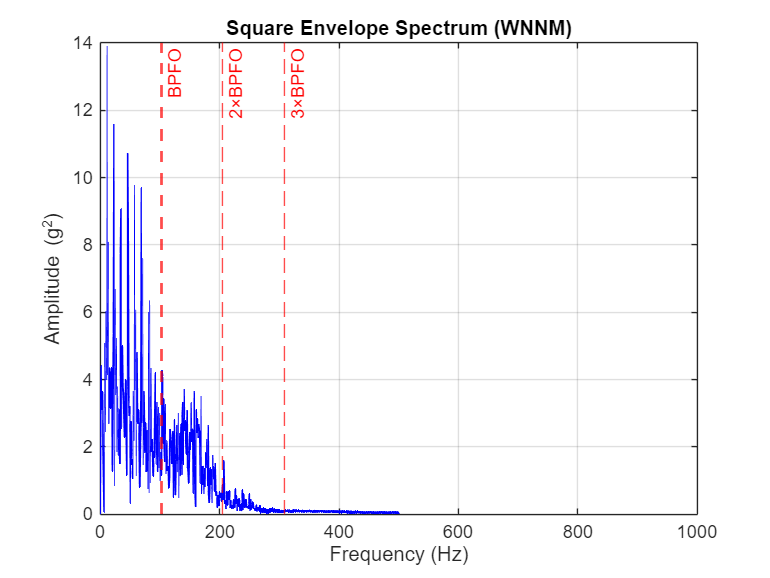

%% ============================================================
%  SQUARE ENVELOPE SPECTRUM 
%  ============================================================

z = x_wnnm_bp(1:Ns);

env = abs(hilbert(z));
env_sq = env.^2;
env_sq = env_sq - mean(env_sq);

L = length(env_sq);
NFFT = 2^nextpow2(L);
ENV_FFT = fft(env_sq, NFFT);

f = Fs*(0:(NFFT/2))/NFFT;
mag = abs(ENV_FFT(1:NFFT/2+1));

figure;
plot(f, mag, 'b', 'LineWidth', 1);
xlim([0 1000]);
xlabel('Frequency (Hz)');
ylabel('Amplitude (g^2)');
title('Square Envelope Spectrum (WNNM)');
grid on;

hold on;
xline(BPFO, '--r', 'BPFO', 'LineWidth', 1.5);
xline(2*BPFO, '--r', '2×BPFO');
xline(3*BPFO, '--r', '3×BPFO');
hold off;